Time evolution using original Non-linear function

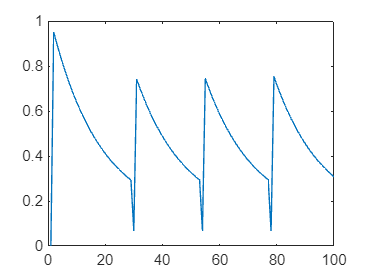

t_steps = 100;
x = zeros(t_steps,1);
x(1) = 0;
for i = 1:t_steps-1
    x(i+1) = F_x(x(i));
end
plot(1:t_steps,x)

Obtaining approximate koopman matrix for linear propagation in lifted space

m = 257; % No. of observables
Xi = zeros(m,t_steps);
x_0 = 0;
Xi(1,1) = 1; 
for i = 1:(m-1)/2
    Xi(2*i,1) = cos(2*pi*i*x_0);
    Xi(2*i+1,1) = sin(2*pi*i*x_0);
end
A = lin_koopman(m);
for i = 1:t_steps-1
    Xi(:,i+1) = A*Xi(:,i);
end
x_est = recover_x(Xi);

Plotting Koopman estimated states with actual states

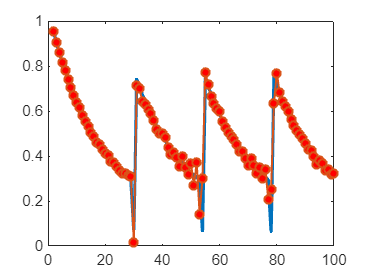

plot(2:t_steps,x(2:end),LineWidth=2)
hold on
plot(2:t_steps, x_est(2:end), '-o', 'MarkerSize', 5, 'MarkerFaceColor', 'red', 'LineWidth', 1.2)
hold off